The system 

% Define the system
num = [1];
den = [1, 3, 2];
sys = tf(num, den);

t = 0:0.01:10; % Time vector
[y, t] = step(sys, t);

Disturbance

% Define time vector and input
u = ones(size(t));

% Defining disturbance
disturbance = 0.1 * sin(2 * pi * 0.5 * t);

% Create closed-loop system
C = pid(1, 1, 0);
sys_closed = feedback(C * sys, 1);

% Create total input
u_disturbed = u + disturbance;

% Simulate the response
[y_disturbed, t] = lsim(sys_closed, u_disturbed', t);

Plot results

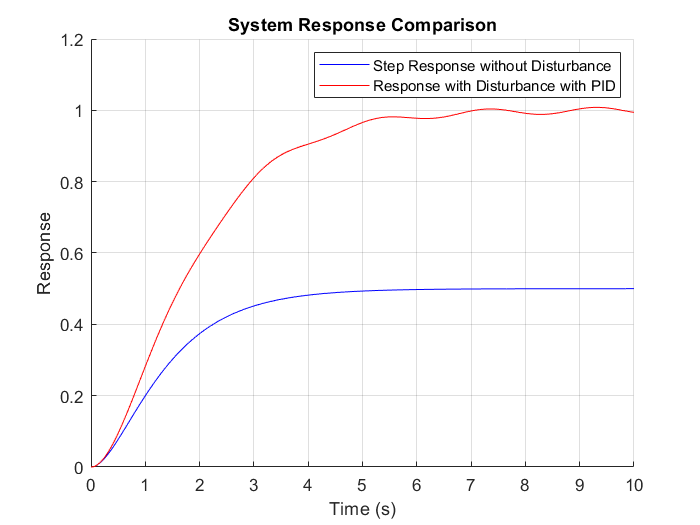

figure;
hold on; 
plot(t, y, 'b', 'DisplayName', 'Step Response without Disturbance');
plot(t, y_disturbed, 'r', 'DisplayName', 'Response with Disturbance with PID');
title('System Response Comparison');
xlabel('Time (s)');
ylabel('Response');
legend;
grid on;